# Franka Emika Panda Singularities (First Set)

clc; clear; close;
panda_model()

#### Define the transformation matrices for the Franka Emika Panda Robot / First Set


vpa(M, 4);

vpa(S, 4);

#### Defining joint limits 

qlim = [-2.8973, 2.8973; -1.7628, 1.7628; -2.8973, 2.8973; -3.0718, -0.0698; -2.8973, 2.8973; -0.0175, 3.7525; -2.8973, 2.8973];

vpa(qlim, 5)

$$ans = \left(\begin{array}{cc} -2.8973 & 2.8973\\ -1.7628 & 1.7628\\ -2.8973 & 2.8973\\ -3.0718 & -0.0698\\ -2.8973 & 2.8973\\ -0.0175 & 3.7525\\ -2.8973 & 2.8973 \end{array}\right)$$

#### Generate a set of discrete joint angles within the joint limits

for i=1:size(qlim, 1)
    Qlim(i, :) = linspace(qlim(i, 1), qlim(i, 2), 10);
end
Qlim

Qlim =    -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -1.7628   -1.3711   -0.9793   -0.5876   -0.1959    0.1959    0.5876    0.9793    1.3711    1.7628
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -3.0718   -2.7382   -2.4047   -2.0711   -1.7376   -1.4040   -1.0705   -0.7369   -0.4034   -0.0698
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -0.0175    0.4014    0.8203    1.2392    1.6581    2.0769    2.4958    2.9147    3.3336    3.7525
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973


#### Define Singular Configurations (Define all possible configs)

Q1 = Qlim(1, :);
Q2 = [0];
Q3 = [pi/2, -pi/2];
Q4 = Qlim(4, :);
Q5 = [pi/2, -pi/2];
Q6 = Qlim(6, :);
Q7 = Qlim(7, :);

#### Generate all possible combinations of joint angles for the robot

Q = unique(combvec(Q1, Q2, Q3, Q4, Q5, Q6, Q7)', 'rows');
Q

Q =    -2.8973         0   -1.5708   -3.0718   -1.5708   -0.0175   -2.8973
   -2.8973         0   -1.5708   -3.0718   -1.5708   -0.0175   -2.2535
   -2.8973         0   -1.5708   -3.0718   -1.5708   -0.0175   -1.6096
   -2.8973         0   -1.5708   -3.0718   -1.5708   -0.0175   -0.9658
   -2.8973         0   -1.5708   -3.0718   -1.5708   -0.0175   -0.3219
   -2.8973         0   -1.5708   -3.0718   -1.5708   -0.0175    0.3219
   -2.8973         0   -1.5708   -3.0718   -1.5708   -0.0175    0.9658
   -2.8973         0   -1.5708   -3.0718   -1.5708   -0.0175    1.6096
   -2.8973         0   -1.5708   -3.0718   -1.5708   -0.0175    2.2535
   -2.8973         0   -1.5708   -3.0718   -1.5708   -0.0175    2.8973


#### Remove duplicate joint angles

uniqueQ = unique(Q, 'rows');
numDuplicates = size(Q,1) - size(uniqueQ,1)

numDuplicates = 0

####  Compute the forward kinematics for each unique set of joint angles

for i = 1:size(uniqueQ,1)
    T1 = FK_SpaceForm(S, M, uniqueQ(i, 1: 7)');
    X(i) = T1(1, 4);
    Y(i) = T1(2, 4);
    Z(i) = T1(3, 4);
end

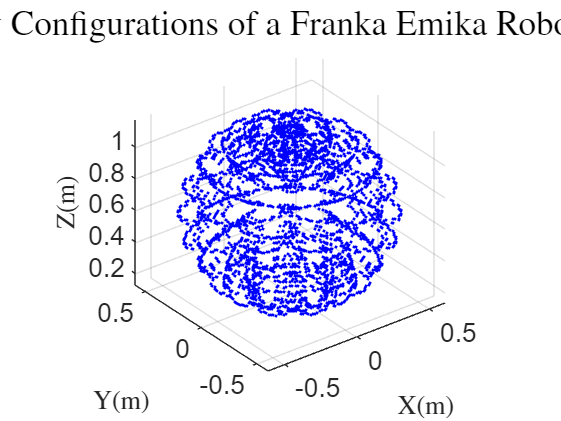

%distance = sqrt(X.^2 + Y.^2 + Z.^2); % compute distance from origin
%c = distance/max(distance); % normalize distances to [0,1]

scatter3(X, Y, Z, 'b.');
% colormap jet; % set the color map
% colorbar; % add a color bar to the plot
ax = gca;
ax.FontSize = 18;
xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');
title('Singularity Configurations of a Franka Emika Robot (Config 1)', 'FontSize', 24, 'Interpreter','latex');
axis equal;

%view(0,0);

#### Choose an arbitrary config to visualize

Q1_rndm = Q1(randi(numel(Q1)));
Q2_rndm = [0];
Q3_rndm = [pi/2, -pi/2];
Q4_rndm = Q4(randi(numel(Q4)));
Q5_rndm = [pi/2, -pi/2];
Q6_rndm = Q6(randi(numel(Q6)));
Q7_rndm = Q7(randi(numel(Q7)));

thetas = unique(combvec(Q1_rndm, Q2_rndm, Q3_rndm, Q4_rndm, Q5_rndm, Q6_rndm, Q7_rndm)', 'rows');
thetas

thetas =     1.6096         0   -1.5708   -1.0705   -1.5708    2.9147    2.8973
    1.6096         0   -1.5708   -1.0705    1.5708    2.9147    2.8973
    1.6096         0    1.5708   -1.0705   -1.5708    2.9147    2.8973
    1.6096         0    1.5708   -1.0705    1.5708    2.9147    2.8973


Js =          0   -0.9992         0    0.0388    0.8768   -0.4794    0.8630
         0   -0.0388         0   -0.9992    0.0340   -0.0186   -0.1916
    1.0000         0    1.0000         0    0.4797    0.8774    0.4674
         0    0.0129         0    0.6485   -0.0238    0.0298    0.2226
         0   -0.3327         0    0.0252    0.6119   -0.7671    0.6058
         0         0         0   -0.0825   -0.0000   -0.0000   -0.1627


ans = 5

2 linearly dependent joints:
  q3 depends on: q1 
  q6 depends on: q1 q2 q4 


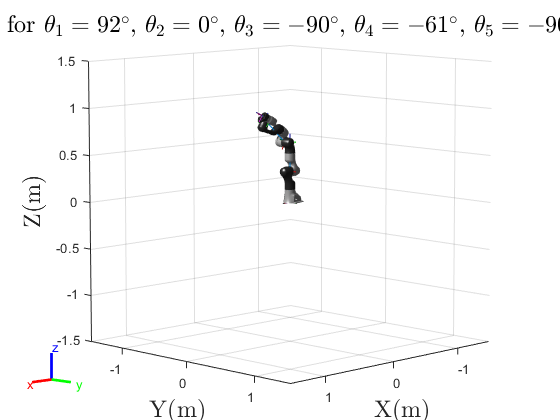

Js =          0   -0.9992         0    0.0388    0.8768    0.4794    0.8456
         0   -0.0388         0   -0.9992    0.0340    0.0186    0.2579
    1.0000         0    1.0000         0    0.4797   -0.8774    0.4674
         0    0.0129         0    0.6485   -0.0238   -0.0298   -0.2689
         0   -0.3327         0    0.0252    0.6119    0.7671    0.5867
         0         0         0   -0.0825   -0.0000   -0.0000    0.1627


ans = 5

2 linearly dependent joints:
  q3 depends on: q1 
  q6 depends on: q1 q2 q4 


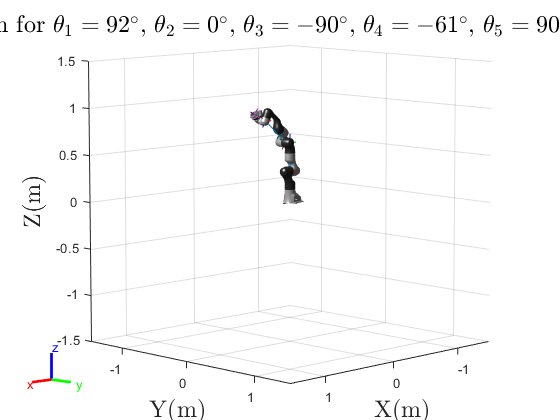

Js =          0   -0.9992         0   -0.0388   -0.8768    0.4794   -0.8630
         0   -0.0388         0    0.9992   -0.0340    0.0186    0.1916
    1.0000         0    1.0000         0    0.4797    0.8774    0.4674
         0    0.0129         0   -0.6485    0.0238   -0.0298   -0.2226
         0   -0.3327         0   -0.0252   -0.6119    0.7671   -0.6058
         0         0         0   -0.0825         0   -0.0000   -0.1627


ans = 5

2 linearly dependent joints:
  q3 depends on: q1 
  q6 depends on: q1 q2 q4 


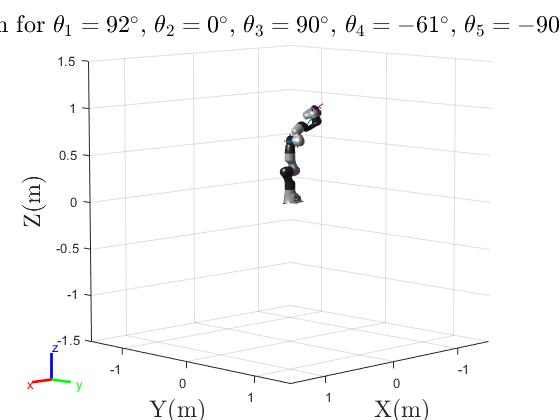

Js =          0   -0.9992         0   -0.0388   -0.8768   -0.4794   -0.8456
         0   -0.0388         0    0.9992   -0.0340   -0.0186   -0.2579
    1.0000         0    1.0000         0    0.4797   -0.8774    0.4674
         0    0.0129         0   -0.6485    0.0238    0.0298    0.2689
         0   -0.3327         0   -0.0252   -0.6119   -0.7671   -0.5867
         0         0         0   -0.0825         0   -0.0000    0.1627


ans = 5

2 linearly dependent joints:
  q3 depends on: q1 
  q6 depends on: q1 q2 q4 


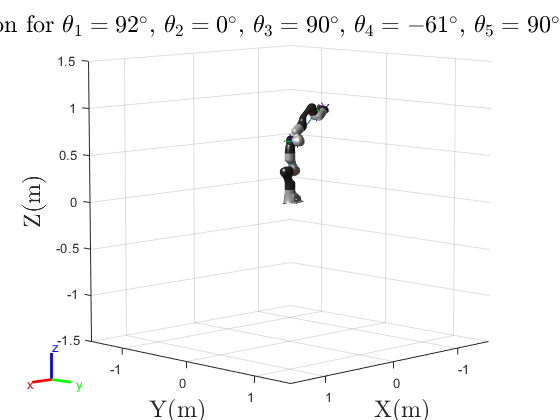


for theta = thetas'
    Js = J_SpaceForm(S, theta)
    rank(Js)
    jsingu(Js)
    robot = importrobot('Franka_Emika_Panda.urdf');
    robot.DataFormat = 'column';

    figure;

    str = "Singular Configuration for ";
    for i= 1:numel(theta)
        str = str + "$\theta_" + num2str (i) + "=" +num2str(round(rad2deg(theta(i)))) + "^ \circ $, ";
    end

    show(robot,theta,'Visuals','on','Frames','on');
    xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
    ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
    zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');

    title(str, 'FontSize', 18, 'Interpreter','latex');

end